%megállított opciókról szóló tétel: megállított martingál is martingál
n=1000;m=1000;
[w,t] = wiener(n,m);


a =1;
tic;
wf = w;
for i = 1:m
    tau = find(w(:,i)>a,1,"first");
    wf(tau:end,i) = a;
end
toc;

Elapsed time is 0.037337 seconds.


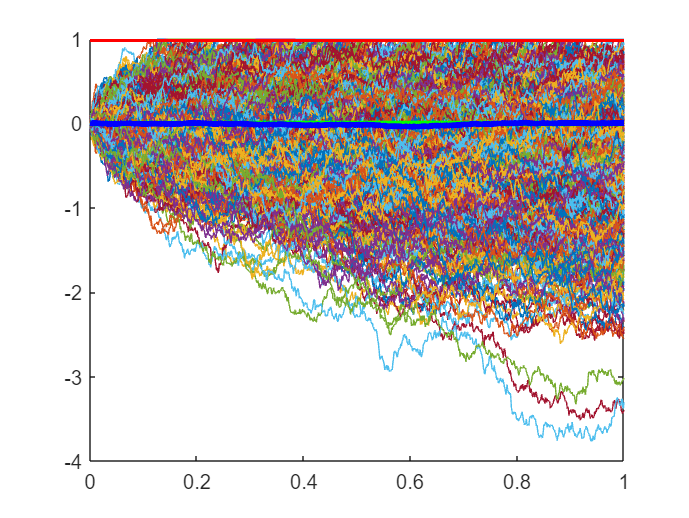

%d = cumsum(w>a);
%wf = (d==0).*w+(d>0)*a;
plot(t,wf);
hold on;
plot(t,ones(size(t))*a,'r','LineWidth',3);
plot(t,zeros(size(t)),'g','LineWidth',3);
plot(t,mean(wf,2),'b','LineWidth',3);
hold off;

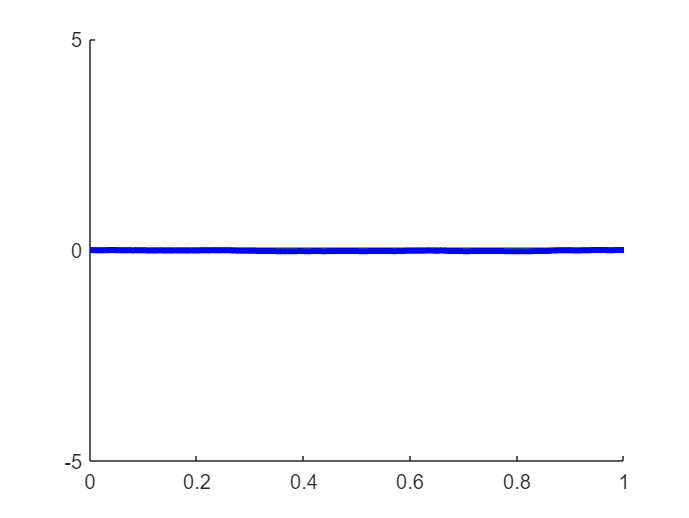

%Mi van ha ugyanezt csináljuk Poisson folyamattal?
isplot=false;
n = 100;m= 10000;
lambda = 10; 
pf = zeros(n+1,m);
t=0:1/n:1;
for i = 1:m
    s = 0;
    while s<=1
        s = s+exprnd(1/lambda);
        if s<=1 %garantálja, hogy ne adjon olyan koordinátát ami nem létezik.
            pf(ceil(s*n),i)=randn;
        end
    end
end
a =8.6;
pf = cumsum(pf);
for i = 1:m 
    tau = find(pf(:,i)>=a,1);
    pf(tau:end,i) = pf(tau,i);
end
if isplot
    plot(t,pf);
else 
    clf;
end
hold on;
if isplot
    plot(t,ones(size(t))*a,'r','LineWidth',3);
end
plot(t,zeros(size(t)),'g','LineWidth',3);
plot(t,mean(pf,2),'b','LineWidth',3);
hold off;
ylim([-5,5]);

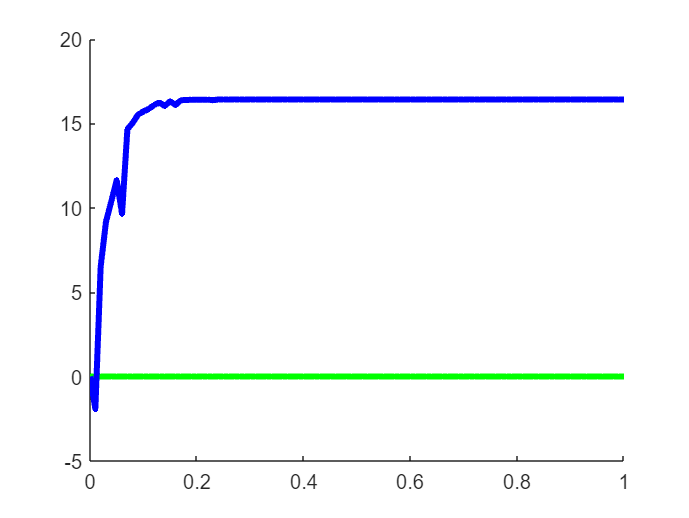

n = 100;m = 10000;
isplot=false;
t=0:1/n:1;
a =1;
pf = [zeros(1,m) ; trnd(1,n,m)];
for i = 1:m 
    tau = find(pf(:,i)>=a,1);
    pf(tau:end,i) = pf(tau,i);
end
if isplot
    plot(t,pf); %mindig növekszik a hiba
else 
    clf;
end
hold on;
if isplot
    plot(t,ones(size(t))*a,'r','LineWidth',3);
end
plot(t,zeros(size(t)),'g','LineWidth',3);
plot(t,mean(pf,2),'b','LineWidth',3);
hold off;